### Computational Methods in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Boundary Value Problems

**Learning outcomes**

On successful completion of this page readers will be able to:

- Understand the definition of a two-point boundary value problem and the existence and uniqueness of its solutions.

- Apply the shooting method to solve a boundary value problem.

- Implement the Secant method to calculate estimates of the initial value.

- Implement the finite-difference method to solve boundary value problems.

- Implement the Thomas algorithm to solve a tridiagonal linear system of equations.

## General two-point boundary value problem

A [**Boundary Value Problem**](https://en.wikipedia.org/wiki/Boundary_value_problem) (BVP) is an Ordinary Differential Equation (ODE) where the solutions at the boundaries of the domain are known. A common type of a BVP is the **two-point BVP** which is written using a second-order ODE


$$y\prime\prime=f(t,y), \qquad t\in[t_{\min}, t_{\max}], \qquad y(t_{\min}) = y_0, \qquad y(t_{\max}) = y_N, \qquad \qquad (1)$$


for some known values $y_0$ and $y_N$.

### Existence and uniqueness of solutions to boundary value problems

If an Initial Value Problem (IVP) has a solution it will be unique for a particular initial value. This is not true for BVPs which can have a unique solution, no solution or an infinite number of solutions. Consider the following ODE


$$y\prime + y = 0.$$


The general solution is


$$y = c_1 \cos(t) + c_2 \sin(t),$$


and consider the following boundary values

- $y(0) = 0$ and $y\left(\frac{\pi}{6}\right)=1$:


$$0 = c_1\cos(0) + c_2\sin(0) = c_1, \\ 1 = c_1 \cos\left(\frac{\pi}{6}\right) + c_2\sin\left(\frac{\pi}{6}\right)=\frac{\sqrt{3}}{2}c_1 + \frac{1}{2}c_2.$$


              Since $c_1=0$ then $c_2=2$ and this BVP has  the unique solution 


$$y = 2\sin(t).$$


- $y(0)=0$ and $y(\pi)=0$:


$$0 = c_1\cos(0) + c_2\cos(0) = c_1, \\ 0 = c_1 \cos(\pi) + c_2 \sin(\pi) = -c_1.$$


              Here $c_1=0$ and $c_2$ can take any value so this BVP has an infinite number of solutions.

- $y(0)=0$ and $y(2\pi)=1$:


$$0 = c_1\cos(0) + c_2\sin(0)= c_1, \\ 1 = c_1\cos(2\pi) + c_2\sin(2\pi)= c_1.$$


              Here $c_1=0$ and $c_1=1$ which is a contradiction so this BVP does not have a solution.

#### Theorem (uniqueness of the solution to a boundary value problem)

A linear boundary vaule problem of the form


$$y\prime\prime= p(t) y\prime + q(t) y + r(t), \qquad t \in [t_{\min}, t_{\max}], \qquad y(t_{\min})= y_0, \qquad y(t_{\max}) = y_N, \qquad \qquad (1)$$


where $p(t)$, $q(t)$ and $r(t)$ are some functions of $t$ then it has a unique solution if the following are satisfied

- $p(t)$, $q(t)$ are $r(t)$ are continuous on $[t_{\min}, t_{\max}]$;

- $q(t)>0$ for all $t\in [t_{\min}, t_{\max}]$.

#### Example 1

Show that the following BVP has a unique solution


$$y\prime\prime = (t^3 + 5)y + \sin(t), \qquad t\in[0,1], \qquad y(0)=0, \qquad y(1)=1.$$


Comparing this BVP to equation (1) we have


$$p(t) = 0, \\ q(t) = t^3 + 5, \\ r(t) = \sin(t),$$


which are all continuous on $[0,1]$ and $q(t)\geq 5$ for all $t\in[0, 1]$ so this BVP has a unique solution.

## The shooting method

Consider the two-point BVP from equation (1). Since the ODE solvers we use can only be applied to a first-order ODE we need to rewrite the second-order ODE as a system of two first-order ODEs


$$y_1\prime=y_2, \\ 
y_2\prime = f(t, y_1, y_2).$$


Since we have let $y_1=y$ we know that $y_1(t_{\min})=y_0$ from the problem definition but we do not know that value of $y_2(t_{\min})=y\prime(t_{\min})$. To overcome this problem we simply guess this value and compute the solutions to the [Initial Value Problem](https://en.wikipedia.org/wiki/Initial_value_problem) (IVP) and compare the solution of $y_1(t_{\max})$ to $y(t_{\max})=y_N$ and adjust the guess value accordingly. This method is called the [**shooting method**](https://en.wikipedia.org/wiki/Shooting_method) because someone shooting at a target will adjust their next shot based where their previous shot landed.

#### Example 2

Use the shooting method to solve the following BVP


$$y\prime\prime - y\prime - y = 0, \qquad t\in[0, 1], \qquad y(0)=1, \qquad y(1)=2.$$


Rewriting this as a system of first-order ODEs gives


$$y_1\prime = y_2, \qquad \qquad \qquad  y_1(0)=1, \\
y_2\prime = y_1 + y_2, \qquad \qquad y_2(0)=s,$$


where $s$ is a guess of $y'(0)$.

The program below solves the BVP defined here using guess values of $s=1$, $s=2$ and $s=1.5$. The program invokes the Euler method which is defined in the function euler in the Functions section at the bottom of the page to solve the system of ODEs

% Define ODE function
f = @(t, y) [ y(2) , y(1) + y(2) ];

% Define BVP parameters
tspan = [ 0, 1 ];   % t domain
bvals = [ 0, 2 ];   % boundary values
s = [ 1, 2, 1.5 ];  % guess values for y'(0)
h = 0.2;

% Loop through the 3 guess values
for i = 1 : 3
    
    % Solve IVP using the Euler method
    [t, y1] = euler(f, tspan, [ bvals(1) , s(i) ], h);
    
    % Append current solution to y array
    if i == 1
        y = y1;
    else
        y = [ y, y1 ];
    end
    
    % Output solution table
    table = ['\n t      y1      y2\n--------------------\n'];
    for n = 1 : length(t)
        table = [table , sprintf('%3.2f %7.4f %7.4f\n', ...
            t(n), y1(n, 1), y1(n, 2))];
    end
    fprintf(table)
    
end


 t      y1      y2
--------------------
0.00  0.0000  1.0000
0.20  0.2000  1.2000
0.40  0.4400  1.4800
0.60  0.7360  1.8640
0.80  1.1088  2.3840
1.00  1.5856  3.0826

 t      y1      y2
--------------------
0.00  0.0000  2.0000
0.20  0.4000  2.4000
0.40  0.8800  2.9600
0.60  1.4720  3.7280
0.80  2.2176  4.7680
1.00  3.1712  6.1651

 t      y1      y2
--------------------
0.00  0.0000  1.5000
0.20  0.3000  1.8000
0.40  0.6600  2.2200
0.60  1.1040  2.7960
0.80  1.6632  3.5760
1.00  2.3784  4.6238


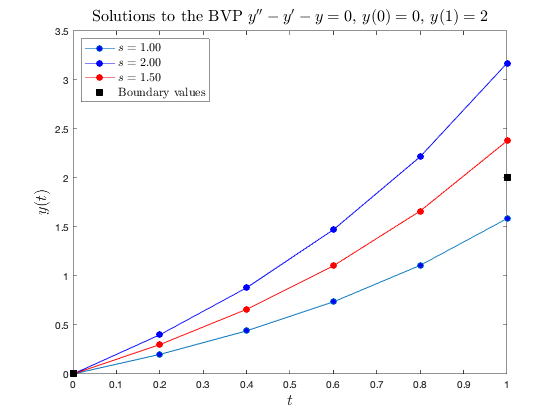

% Plot solutions
plot(t, y(:, 1), 'o-', 'MarkerFaceColor', 'b')
hold on
plot(t, y(:,3), 'bo-', 'MarkerFaceColor', 'b')
plot(t, y(:,5), 'ro-', 'MarkerFaceColor', 'r')
plot(tspan, bvals, 'ks', 'MarkerFaceColor', 'k', 'MarkerSize', 8)
hold off

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' - y' - y = 0$, $y(0)=0$, $y(1)=2$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('$s=1.00$', '$s=2.00$', '$s=1.50$', 'Boundary values');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Comparing the solutions of $y(1)$ to the boundary value of $y(1)=2$ we can see that using $s=1$ results in $y_1(1)=1.5856$ which is too small and using $s=1$ results in $y(1)=3.1712$ which is too large. Choosing a guess of somewhere inbetween such as $s=0.5$ results in $y(1)=2.2384$ which is closer to the exact solution but still not an accurate approximation of $y(1)=2$. We continue to adjust the initial guess value based on the solution at the upper boundary until we get a result that is accurate enough for our needs.

## Improving the guess value using the secant method

To improve the guess value we can use the [**Secant method**](https://en.wikipedia.org/wiki/Secant_method). The Secant method is a root finding algorithm that calculates the value of $s$ where $F(s)=0$ for some function $F$


$$s_{i+1} = s_i - F(s_i)\frac{s_i - s_{i-1}}{F(s_i) - F(s_{i-1})}.$$


This expression is iterated until $|s_i - s_{i-1}|<tol$ where $tol$ is some small number. Since we want the solution of $f'(t_{\max})$ to be equal to the upper boundary value $y_N$ we can define


$$F(s) = f\prime(t_{\max})-y_N,$$


and use the Secant method to calculate $s$.

The function called `shooting_method` below is defined in the Functions section at the bottom fo the page calculates the solution to a BVP using the shooting method with the Secant method to calculate an improved guess value using two starting guess values of $s=1$ and $s=2$. The Secant method is iterated until two successive guess values are within $tol=10^{-6}$ or the number of iterations exceeds `maxiter`.

#### Example 3

Use the shooting method to calculate the solution of the BVP from example 2.

% Solve BVP using the shooting method
[t, y] = shooting_method(@euler, f, tspan, bvals, h, 10);

% Output solution table
table = '\n t      y1      y2\n--------------------\n';
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', ...
        t(n), y(n, 1), y(n, 2))];
end
fprintf(table)


 t      y1      y2
--------------------
0.00  0.0000  1.2614
0.20  0.2523  1.5136
0.40  0.5550  1.8668
0.60  0.9284  2.3512
0.80  1.3986  3.0071
1.00  2.0000  3.8882


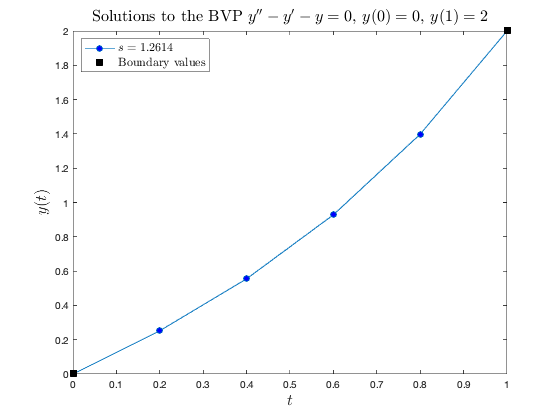

% Plot solutions
plot(t, y(:, 1), 'o-', 'MarkerFaceColor', 'b')
hold on
plot(tspan, bvals, 'ks', 'MarkerFaceColor', 'k', 'MarkerSize', 8)
hold off

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' - y' - y = 0$, $y(0)=0$, $y(1)=2$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend(sprintf('$s=%1.4f$', y(1, 2)), 'Boundary values');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Here the Secant method converged to a guess value of $s=1.2614$ which provides a solution at the upper boundary of $y(1)=2$.

### A note about accuracy

In example 3 we iterated the Secant method until convergence and got a very accurate solution for the value of $y(t_{\max})$. We must be careful not to forget that this solution was obtained using the Euler method which being only first-order so expect it to be relatively innacurate.

The exact solution to the BVP from example 2 above is


$$t = \frac{2e^{\left(1-\sqrt{5}\right)(1-t)/2}\left(e^{\sqrt{5}t} - 1\right)}{e^{\sqrt{5}} - 1}.$$


The code below plots the solution obtained using the Euler method with the guess value of $s=1.2614$ and compares it to the exact solution.

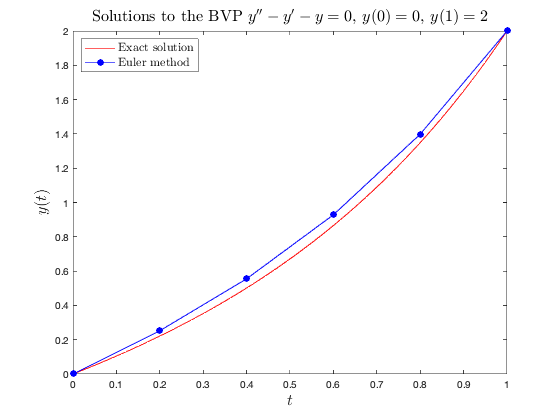

% Define exact solution
exact_sol = @(t) (2 * exp(-0.5 * (sqrt(5) - 1) * (t - 1)) ...
    .* (exp(sqrt(5) * t) - 1)) / (exp(sqrt(5)) - 1);

% Add exact solution to plot
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact_sol(t1), 'r-')
hold on
plot(t, y(:, 1), 'bo-', 'MarkerFaceColor', 'b')
hold off

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' - y' - y = 0$, $y(0)=0$, $y(1)=2$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact solution', 'Euler method');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

So despite the Secant method giving a guess value that gives an accurate solution at the upper bounday, the use of the Euler method does not give an accurate solution in the interior points. One way to improve the accuracy of our approximation is to use a more accurate ODE solver.

The function below calculates the solution to an IVP using the second-order [Runge-Kutta method](https://en.wikipedia.org/wiki/Runge%E2%80%93Kutta_methods) (RK2).

% Solve BVP using the shooting method
[t, y] = shooting_method(@rk2, f, tspan, bvals, h, 10);

% Output solution table
table = '\n t      y1      y2\n--------------------\n';
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', ...
        t(n), y(n, 1), y(n, 2))];
end
fprintf(table)


 t      y1      y2
--------------------
0.00  0.0000  1.0182
0.20  0.2240  1.2625
0.40  0.5062  1.6148
0.60  0.8716  2.1138
0.80  1.3541  2.8128
1.00  2.0000  3.7858


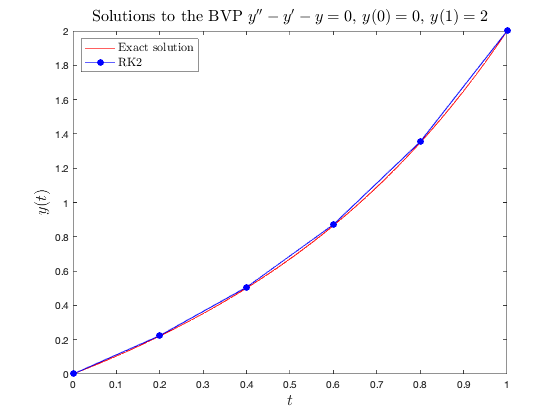

% Plot solution
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact_sol(t1), 'r-')
hold on
plot(t, y(:, 1), 'bo-', 'MarkerFaceColor', 'b')
hold off

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' - y' - y = 0$, $y(0)=0$, $y(1)=2$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact solution', 'RK2');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that we have a much more accurate solution than when we used the Euler method to solve the ODE.

## Finite-difference method

The [**finite-difference method**](https://en.wikipedia.org/wiki/Finite_difference_method) for solving a BVP converts the BVP into a system of algebraic equations by replacing the derivatives in the ODE with finite-difference approximations derived from the [Taylor series](https://en.wikipedia.org/wiki/Taylor_series). The system of equations is then solved to obtain an approximation of the solution to the BVP.

The solution is approximated at discrete points called **nodes** that are equally spaced in the domain. If 𝑁N nodes are used to **discretise** the domain then the spacing between two nodes is


$$h = \frac{t_{\max} - t_{\min}}{N-1},$$


and the $t$ value of the $i$th node is calculated using $t_i = t_{\min} + ih$ and the solution $y(t_i)$ is denoted by $y_i$ for brevity. The derivatives of $y_i$ are approximated using values of neighbouring nodes $y_{i+1}$, $y_{i-1}$ etc. using expressions derived by truncating the Taylor series and rearranging to make the derivative term the subject. Some common finite-difference approximations are listed in the table below.


$$\begin{array}{cccl}
\textbf{Derivative} & \textbf{Finite-difference approximation} & \textbf{Order of accuracy} & \textbf{Name} \\
y\prime & \frac{y_{i+1} - y_i}{h} & \text{1st} & \text{forward difference} \\
y\prime & \frac{y_i - y_{i-1}}{h} & \text{1st} & \text{backward difference} \\
y\prime & \frac{y_{i+1} - y_{i-1}}{h} & \text{2nd} & \text{central difference} \\
y\prime\prime & \frac{y_{i-1} - 2y_i + y_{i+1}}{h^2} & \text{2nd} & \text{symmetric difference}
\end{array}$$


### Finite-difference solutions to a boundary value problem

The solution to a BVP using then finite-difference method is determined by approximating the derivatives in the ODE using finite-differences. Consider the following BVP


$$y\prime\prime = f(t, y), \qquad t \in [t_{\min}, t_{\max}], \qquad y(t_{\min}) = y_0, \qquad y(t_{\max}) = y_N.$$


Using the [symmetric difference](http://localhost:8888/notebooks/boundary_value_problems.ipynb#symmetric_difference) to approximate $y\prime\prime$ in the ODE we have


$$y_{i-1} - 2y_i + y_{i+1} = h^2 f(t_i, y_i), \qquad i = 1, 2, \ldots, N-1.$$


This is a linear system of $N-1$ equations. The values of the nodes at the lower and upper boundaries, $y_0$ and $y_N$, are known so the we can reduce this system to $N-3$ equations where


$$\qquad \, -2y_1 + y_2 = h^2 f(t_1, y_1) - y_0, \\
y_{i-1} - 2y_i + y_{i+1} = h^2 f(t_i, y_i), \qquad i = 2, 3, \ldots, N-2,\\
\quad y_{N-2} - 2y_{N-1} = h^2 f(t_{N-1}, y_{N-1}) - y_N.$$


This can be expressed as a matrix equation


$$\pmatrix{
-2 & 1 \cr
1 & -2 & 1 \cr
& \ddots & \ddots & \ddots \cr
& & 1 & -2 & 1 \cr
& & & 1 & -2
}
\pmatrix{ y_1 \cr y_2 \cr \vdots \cr y_{N-2} \cr y_{N-1} } =
\pmatrix{ f(t_1, y_1) - y_0 \cr f(t_2,y_2) \cr \vdots \cr f(t_{N-2},y_{N-2}) \cr f(t_{N-1},y_{N-1}) - y_N}.$$


### The Thomas algorithm

We have seen above that the matrix equation resulting from a second-order two-point BVP has a tridiagnal coefficient matrix. This means we can use the [**Thomas Algorithm**](https://en.wikipedia.org/wiki/Tridiagonal_matrix_algorithm) which is a form of Gaussian elimination and very efficient for solving tridiagonal systems.

Given a linear tridagonal system of the form $A\mathbf{x}=\mathbf{d}$ then let $a_i$, $b_i$ and $c_i$ be the elements on the lower, main and upperdiagonals of the coefficient matrix $A$ and $d_i$ be the values of the right-hand side vector $\mathbf{d}$


$$\pmatrix{
b_0 & c_0 \cr
a_1 & b_1 & c_1 \cr
& \ddots & \ddots & \ddots \cr
& & a_{N-1} & b_{N-1} & c_{N-1} \cr
& & & a_N & b_N
}
\pmatrix{ x_1 \cr x_2 \cr \vdots \cr x_{N-2} \cr x_{N-1} } =
\pmatrix{ d_0 \cr d_1 \cr \vdots \cr d_{N-1} \cr d_N }.$$


The Thomas algorithm first uses a forward sweep to apply row operations to the values of $b_i$ and $d_i$ before solving for the values of $x_i$ by back substitition.

Forward sweep:


$$b_i = b_i - \frac{a_i}{b_{i-1}}c_{i-1}, \qquad i = 2, 3, \ldots, N, \\
d_i = d_i - \frac{a_i}{b_{i-1}}d_{i-1}, \qquad i = 2, 3, \ldots, N.$$


Back substitution:


$$x_n = \frac{d_N}{b_N}, \\
x_i = \frac{d_i - c_ix_{i+1}}{b_i}, \qquad i = N-1, N-2, \ldots, 1.$$


The function called tridiag_solver below is defined in the Functions section at the bottom of the page solves a tridiagonal linear system using the Thomas algortihm given inputs of the arrays for $a_i$, $b_i$, $c_i$ and $d_i$.

#### Example 4

Use the finite-difference method to solve the BVP given in example 2


$$y\prime\prime - y\prime - y = 0, \qquad t \in [0, 1], \qquad y(0)=1, \qquad y(1) = 2.$$


Using a forward difference to approximate $y\prime$ and a symmetric difference to approximate $y\prime\prime$ we have


$$\frac{y_{i-1} - 2y_i + y_{i+1}}{h^2} - \frac{y_{i+1} - y_i}{h} - y_i=0,$$


which can be simplified to


$$y_{i-1} + (h-h^2 - 2)y_i + (1 - h)y_{i+1}=0,$$


with the nodes adjacent to the lower and upper boundaries


$$(h - h^2 - 2)y_1 + (1 - h)y_2 = -y_0, \\
\,\,\,\,\,y_{N-2} + (h-h^2 - 2)y_{N-1} = -(1 - h)y_N.$$


We can write the liner system as the matrix equation


$$\pmatrix{
h - h^2 - 2 & 1 - h \cr
1 & h - h^2 - 2 & 1 - h \cr
& 1 & h - h^2 - 2 & 1 - h \cr
& & \ddots & \ddots & \ddots \cr
& & & 1 & h - h^2 - 2 & 1 - h \cr
& & & & 1 & h - h^2 - 2
}
\pmatrix{y_1 \cr y_2 \cr y_3 \cr \vdots \cr y_{N-2} \cr y_{N-1}}
=
\pmatrix{-y_0 \cr 0 \cr 0 \cr \vdots \cr 0 \cr -y_N}.$$


The code below defines this linear system and solves it using the Thomas algorithm.

% Define BVP parameters
tspan = [ 0, 1 ];
bvals = [ 0, 2 ];
h = 0.2;

% Discretise domain
N = floor((tspan(2) - tspan(1)) / h) + 1;
t = tspan(1) : h : tspan(2);
y = zeros(size(t));
y(1) = bvals(1);
y(N) = bvals(2);

% Define linear system
a = ones(N-2, 1);
b = (h - h^2 - 2) * ones(N-2, 1);
c = (1 - h) * ones(N-2, 1);
d = zeros(N-2, 1);
d(1) = d(1) - y(1);
d(N-2) = d(N-2) - (1 - h) * y(N);

% Solve linear system
y(2:N-1) = tridiag_solver(a, b, c, d);

% Output solution table
table = '\n t    fin diff  Exact\n-----------------------\n';
for n = 1 : length(t)
    table = [table , sprintf('%3.2f  %7.4f   %7.4f\n', t(n), y(n), exact_sol(t(n)))];
end
fprintf(table)


 t    fin diff  Exact
-----------------------
0.00   0.0000    0.0000
0.20   0.2060    0.2213
0.40   0.4738    0.5014
0.60   0.8322    0.8658
0.80   1.3219    1.3494
1.00   2.0000    2.0000


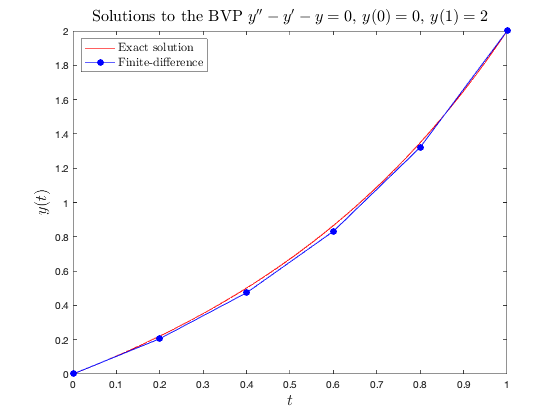

% Plot solution
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact_sol(t1), 'r-')
hold on
plot(t, y, 'bo-', 'MarkerFaceColor', 'b')
hold off

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' - y' - y = 0$, $y(0)=0$, $y(1)=2$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact solution', 'Finite-difference');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

### Accuracy vs number of nodes

The solutions seen in example 4 seem to show that the finite-difference method produces reasonably accurate results for this BVP. One way to improve on the accuracy of our solution is to increase the number of nodes used.

#### Example 5

Solve the following BVP using the finite-difference method with $N=51$ and $N=501$ nodes


$$y\prime\prime + 3ty\prime + 7y = \cos(2t), \qquad t \in [0, 3], \qquad y(0) = 1, \qquad y(3) = 0.$$


Using forward and symmetric differences to approximate $y\prime$ and $y\prime\prime$ respectively results in the following system


$$\qquad \quad (7h^2 - 3ht_1 -2)y_1 + (1 + 3ht_1)y_2 = h^2\cos(2t_1)-y_0, \\
y_{i-1} + (7h^2 - 3ht_i - 2)y_i + (1 + 3ht_i)y_{i+1} = h^2\cos(2t_i), \qquad \qquad i=2, 3, \ldots, N-3, \\
\qquad \quad \,\,\,\,\,y_{N-2} + (7h^2 - 3ht_{N-1} - 2)y_{N-1} = h^2\cos(2t_{N-1}) - (1 + 3ht_N)y_N.$$


The code below calculates the solution to this system using $N=51$ and $N=501$ nodes and compares the solutions in a plot.

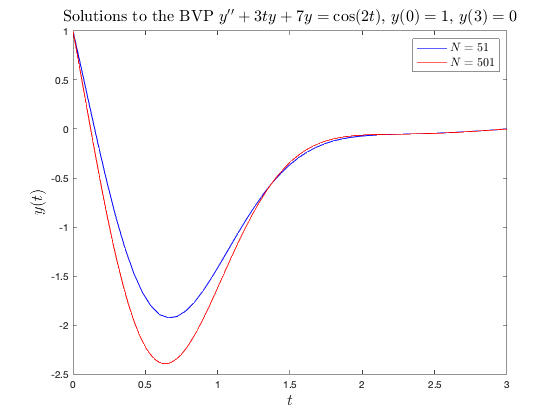

clear

% Define BVP parameters
tspan = [ 0, 3 ];
bvals = [ 1, 0 ];

% Solve using 51 and 501 nodes
for N = [ 51, 501]
    
    % Discretise domain
    h = (tspan(2) - tspan(1)) / (N - 1);
    t = linspace(tspan(1), tspan(2), N);
    y = zeros(size(t));
    y(1) = bvals(1);
    y(N) = bvals(2);
    
    % Define linear system
    a = ones(N-2, 1);
    b = 7 * h ^ 2 - 3 * h * t(2:N-1) - 2;
    c = 1 + 3 * h * t(2:N-1);
    d = h ^ 2 * cos(2 * t(2:N-1));
    d(1) = d(1) - y(1);
    d(N-2) = d(N-2) - (1 + 3 * h * t(N)) * y(N);
    
    % Solve linear system
    y(2:N-1) = tridiag_solver(a, b, c, d);
    
    % Save solutions
    if N == 51
        t1 = t;
        y1 = y;
    else
        t2 = t;
        y2 = y;
    end
end

% Plot solution
plot(t1, y1, 'b-')
hold on
plot(t2, y2, 'r-')
hold off

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' + 3ty + 7y = \cos(2t)$, $y(0)=1$, $y(3)=0$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('$N=51$', '$N=501$');
set(leg, 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that the solution using $N=51$ nodes is inaccurate when compared to the solution using $N=501$ nodes (we expect the more nodes used the more accurate the result). As well as increasing the number of nodes, another way we can improve our solution is to use a higher order approximation of the $y\prime$ derivative.

Using the central difference (which is second-order accurate) to approximate $y\prime$ results in the following tridiagonal linear system


$$\qquad \qquad \qquad \qquad \,\,\,\,(7h^2 - 2)y_1 + \left(1 + \frac{3}{2}h\right) y_2 = h^2 \cos(2t_1) - \left(1 - \frac{3}{2}ht_0\right)y_0, \\
\left( 1 - \frac{3}{2} h t_i\right) y_{i-1} + (7h^2 - 2) y_i + \left(1 + \frac{3}{2} h t_i\right)y_{i+1} = h^2 \cos(2t_i), \qquad \qquad i = 2, 3, \ldots, N-2, \\
\qquad \qquad \,\,\,\,\left(1 - \frac{3}{2}ht_{N-1}\right)y_{N-2} + (7h^2 - 2)y_{N-1} = h^2 \cos(2t_{N-1}) - \left(1 + \frac{3}{2}ht_N\right)y_N.$$


The code below solves this system using $N=51$ and $N=501$ nodes and compares it to the solution using $N=501$ nodes for the first-order foward difference to approximate the $y\prime$ term.

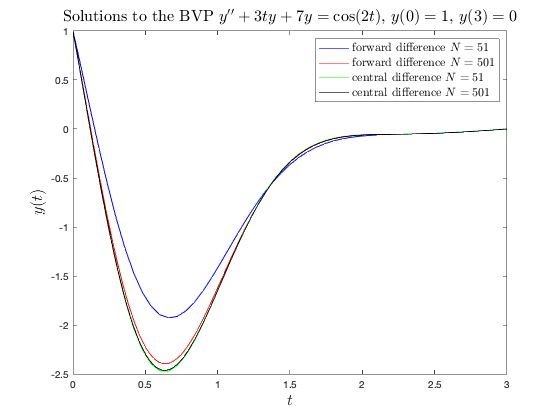

% Solve using 51 and 501 nodes
for N = [ 51, 501]
    
    % Discretise domain
    h = (tspan(2) - tspan(1)) / (N - 1);
    t = linspace(tspan(1), tspan(2), N);
    y = zeros(size(t));
    y(1) = bvals(1);
    y(N) = bvals(2);
    
    % Define linear system
    a = 1 - 3 / 2 * h * t(2:N-1);
    b = (7 * h ^ 2 - 2) * ones(N-2, 1);
    c = 1 + 3 / 2 * h * t(2:N-1);
    d = h ^ 2 * cos(2 * t(2:N-1));
    d(1) = d(1) - (1 - 3 / 2 * h * t(1)) * y(1);
    d(N-2) = d(N-2) - (1 + 3 / 2 * h * t(N)) * y(N);
    
    % Solve linear system
    y(2:N-1) = tridiag_solver(a, b, c, d);
    
    % Save solutions
    if N == 51
        t3 = t;
        y3 = y;
    else
        t4 = t;
        y4 = y;
    end
end

% Plot solutions
plot(t1, y1, 'b-', t2, y2, 'r-', t3, y3, 'g-', t4, y4, 'k-')

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the BVP $y'' + 3ty + 7y = \cos(2t)$, $y(0)=1$, $y(3)=0$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('forward difference $N=51$', 'forward difference $N=501$', ...
    'central difference $N=51$', 'central difference $N=501$');
set(leg, 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that there is very little difference between the solutions using $N=51$ and $N=501$ nodes for the central difference approximation showing that $N=51$ nodes is adequate.

## Summary

- A two-point boundary value problem is defined by a second-order ODE where the solutions at the lower and upper boundaries are known.

- A boundary value problem can have a unique solution, an infinitely number of solutions or no solutions.

- The shooting method guesses the initial value for $y'\prime(0)$ and alters the guess by comparing the computed solution at the upper boundary to the known solution.

- The Secant method is used to calculate improved estimates of the guess value.

- The finite-difference method uses finite-difference approximations of the derivatives in the ODE to derive a tridiagonal linear system of equations that approximates the solution to the boundary value problem.

- The Thomas algorithm is a very efficient algorithm for solving tridiagonal linear systems of equations.

- The higher the order of a method, the fewer nodes are required to achieve the same accuracy.

## Exercises

1.    Determine which of the following BVPs have a unique solution:

        (a)    $y\prime\prime=-\frac{4}{t}y\prime + \frac{2}{t^2}y - \frac{2\ln(t)}{t^3}, \qquad t \in [1, 2], \qquad y(1) = \frac{1}{2}, \qquad y(2) = \ln(2)$;

        (b)    $y\prime\prime = e^t + y\cos(t) - (t+1)y\prime, \qquad t \in [0, 2], \qquad y(0)=1, \qquad y(2) = \ln(3)$;

        (c)    $y\prime\prime = (t^3 + 5)y + \sin(t), \qquad t \in [0, 1], \qquad y(0)=0, \qquad y(1) = 1$;

        (d)    $y\prime\prime = (5y + \sin (3t))e^t, \qquad t\in [0, 1], \qquad y(0)=0, \qquad y(1)=0$.

2.     Consider the following BVP


$$y\prime\prime = 2t, \qquad t \in [0, 2], \qquad y(0)=1, \qquad y(2)=3.$$


        Using a pen and calculator, calculate the Euler method solutions using a step length of $h=0.5$ for each of the following guess values:

        (a)    $s=1$;

        (b)    $s=-1$.

3.    Use the Secant method to calculate the next value of $s$ for your solutions to the BVP in question 2 and hence calculate the Euler method using this new guess value. 

4.    Using a pen and calculator, calcualte the solution of the BVP in question 2 using the finite-difference method with a step length $h=0.5$.

5.    Write a MATLAB program to repeat questions 2 and 3 using a step length of $h=0.1$. The exact solution to this BVP is $y=\frac{1}{3}t^3 - \frac{1}{3}t+1$. Produce a plot of the numerical solutions and exact solution on the same set of axes.

## Functions

The various functions used in this page are defined in this section.

#### The Euler method for solving a system of ODEs

function [t, y] = euler(f, tspan, y0, h)

% Calculuates the solution to an IVP expressed using a system of first-order
% ODEs using the Euler method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, length(y0));
t(1) = tspan(1);
y(1, :) = y0';

% Solver loop
for n = 1 : nsteps
    y(n + 1, :) = y(n, :) + h * f(t(n), y(n, :));
    t(n + 1) = t(n) + h;
end

end

#### The second-order Runge-Kutta method for solving a system of ODEs

function [t, y] = rk2(f, tspan, y0, h)

% Calculuates the solution to an IVP expressed using a system of first-order
% ODEs using the second-order Runge-Kutta method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, length(y0));
t(1) = tspan(1);
y(1, :) = y0';

% Solver loop
for n = 1 : nsteps
    k1 = f(t(n), y(n, :));
    k2 = f(t(n) + 0.5 * h, y(n, :) + 0.5 * h * k1);
    y(n + 1, :) = y(n, :) + h * k2;
    t(n + 1) = t(n) + h;
end

end

#### The shooting method for solving a BVP

function [t, y] = shooting_method(odesolver, f, tspan, bvals, h, maxiter)

% Calculates the solution to a BVP using the shooting method with the Secant method
% used to determine the guess values

% Iterate until successive guess values agree
s0 = 1;
s1 = 2;
F0 = 1;

for i = 1 : maxiter
    
    % Solve IVP using current guess value
    [t, y] = odesolver(f, tspan, [ bvals(1) , s1 ], h);
    
    % Use Secant method to calculate next guess value after first iteration
    F1 = y(end, 1) - bvals(2);
    s2 = s1 - F1 * (s1 - s0) / (F1 - F0);
    s0 = s1;
    s1 = s2;
    F0 = F1;
    
    % Check for convergence
    if abs(s1 - s0) < 1e-6
        break
    end
end

end

#### The Thomas algorithm for solving a tridiagonal linear system

function x = tridiag_solver(a, b, c, d)

% Calculates the solution to a tridiagonal linear system of equations using
% the Thomas algorithm

% Forward sweep
N = length(b);
for i = 2 : N
    w = a(i) / b(i-1);
    b(i) = b(i) - w * c(i-1);
    d(i) = d(i) - w * d(i-1);
end

% Back substitution
x = zeros(size(b));
x(N) = d(N) / b(N);
for i = N - 1 : -1 : 1
    x(i) = (d(i) - c(i) * x(i+1)) / b(i);
end

end